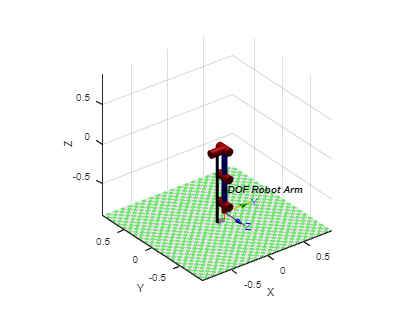

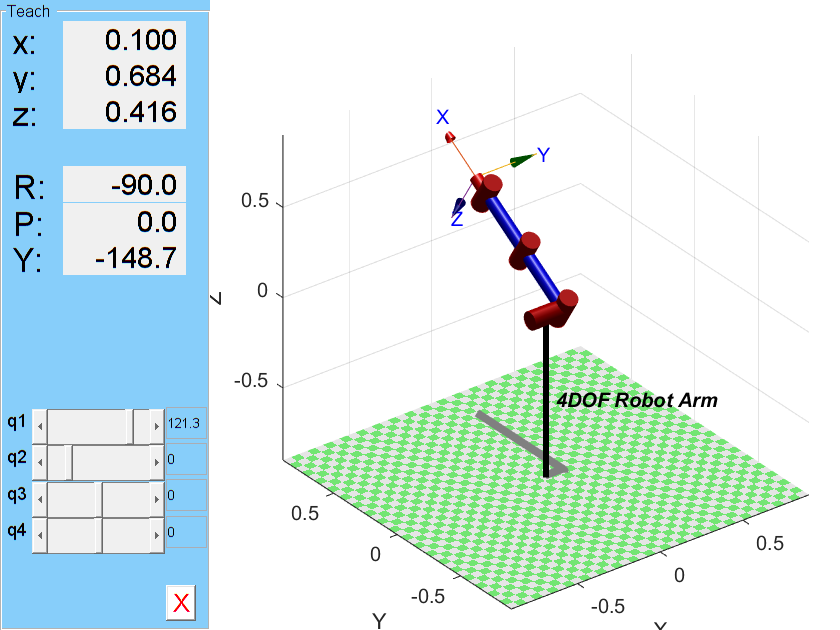



clear all               
close all               
clc                     

L1 = 0.1;  
L2 = 0.35; 
L3 = 0.35;  
L4 = 0.1; 

L(1) = Link('d', L1, 'a', 0, 'alpha', pi/2);       
L(2) = Link('d', 0, 'a', L2, 'alpha', 0);         
L(3) = Link('d', 0, 'a', L3, 'alpha', 0);         
L(4) = Link('d', 0, 'a', L4, 'alpha', 0);        

robot_arm = SerialLink(L, 'name', '4DOF Robot Arm');

%joint limit
robot_arm.qlim = [[-pi pi]; [-pi/4 7*pi/6]; [-5*pi/6 5*pi/6]; [-5*pi/6 5*pi/6]];

%adjust armbase
robot_arm.base = troty(pi/2); 

%forward kinematics at default pose [0, 0, 0, 0]
T = robot_arm.fkine([0, 0, 0, 0]);

figure();
robot_arm.plot([0, 0, 0, 0]);

figure();
robot_arm.teach;